# Converting Code to a Local Function

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data and plots the distribution of total medal counts

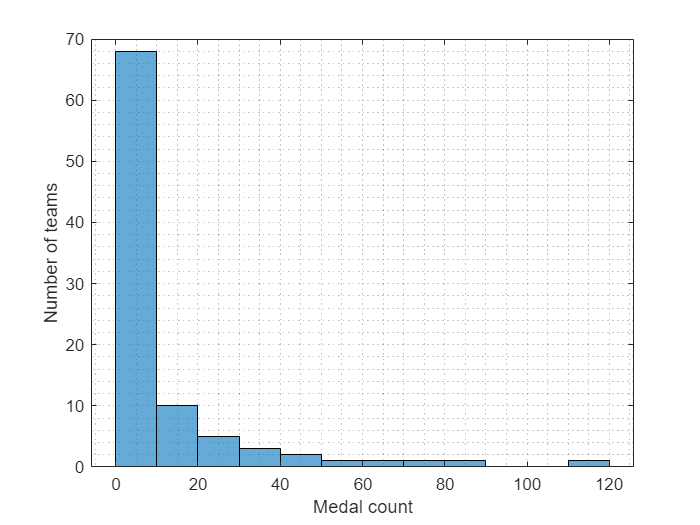

golds = table2array(readtable("../data/medals.xlsx", "Sheet", "golds", "ReadVariableNames", false));
medals = table2array(readtable("../data/medals.xlsx", "Sheet", "medals", "ReadVariableNames", false));
histogram(medals)
grid minor
xlabel("Medal count")
ylabel("Number of teams")

## Task 1

pp = paretoperc(medals)

pp = 75.6481

## Task 2

ppgold = paretoperc(golds)

ppgold = 73.8235

function pp = paretoperc(x)
% Cumulative contribution of data points (in order)
cc = cumsum(sort(x(:),"descend"));  % (:) to ensure column vector
cc = 100*cc/cc(end);                % Normalize to percentage
% Corresponding percentiles (column vector to match cc)
pct = (1:numel(x))';
pct = 100*pct/numel(pct);           % Normalize to percentage
% Find the number of data values needed so that
% P% of the data is in (100-P)% of the values
idx = find(cc >= (100-pct),1,"first");
pp = cc(idx);
end